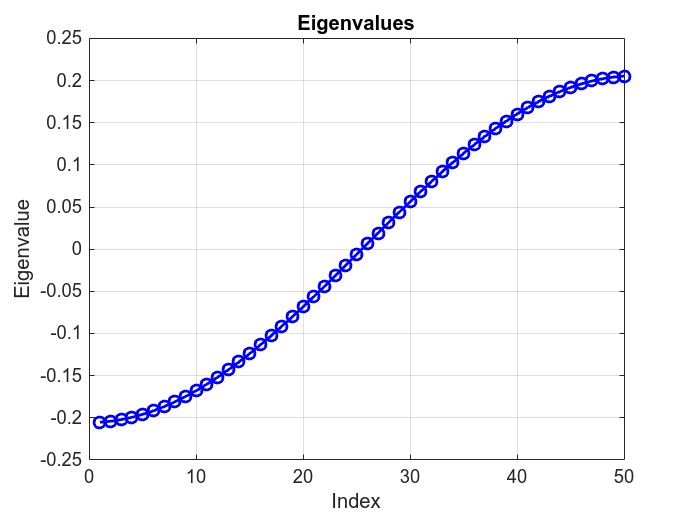

clear; clc;




%% ----------------------------------------------------
%  Helper function to convert "real imag real imag ..." rows → complex matrix
% ----------------------------------------------------
convert_to_complex = @(Mraw) ...
    Mraw(:,1:2:end) + 1i*Mraw(:,2:2:end);


%% ----------------------------------------------------
%  Load eigenvalues
% -----------------------------------------------------
Eraw = load('eigenvalues.txt');   % col1=Re, col2=Im
E = Eraw(:,1) + 1i*Eraw(:,2);

figure;
plot(real(E), 'bo-', 'LineWidth', 1.5); grid on;
xlabel('Index');
ylabel('Eigenvalue');
title('Eigenvalues');

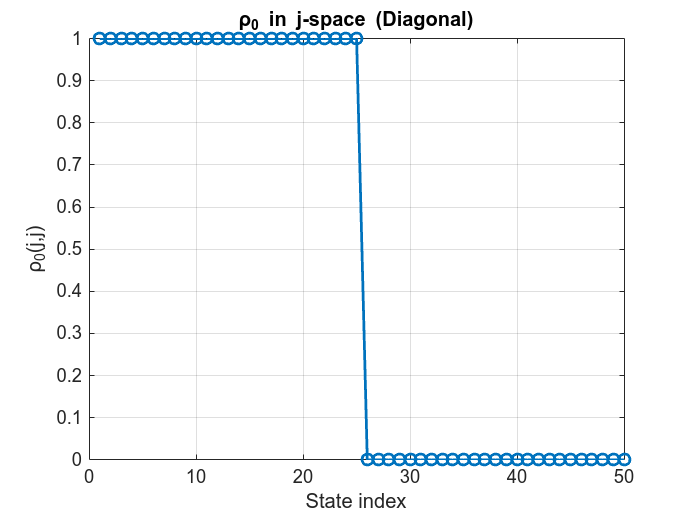






%% ----------------------------------------------------
%  Load rho0 in j-space (eigenbasis)
% -----------------------------------------------------
rho0j_raw = load('rho0_j_space.txt');
rho0_j = convert_to_complex(rho0j_raw);

figure;

plot(real(diag(rho0_j)), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('State index');
ylabel('ρ_0(j,j)');
title('ρ_0 in j-space (Diagonal)');

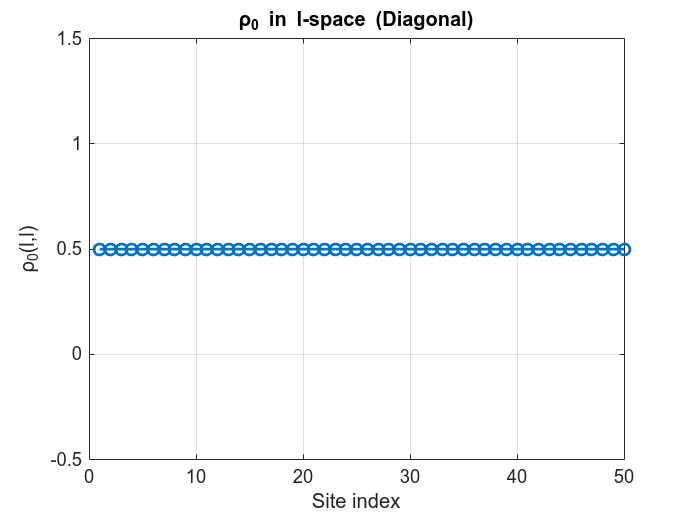





%% ----------------------------------------------------
%  Load rho0 in l-space (site basis)
% -----------------------------------------------------
rho0l_raw = load('rho0_l_space.txt');
rho0_l = convert_to_complex(rho0l_raw);

figure;

plot(real(diag(rho0_l)), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Site index');
ylabel('ρ_0(l,l)');
title('ρ_0 in l-space (Diagonal)');

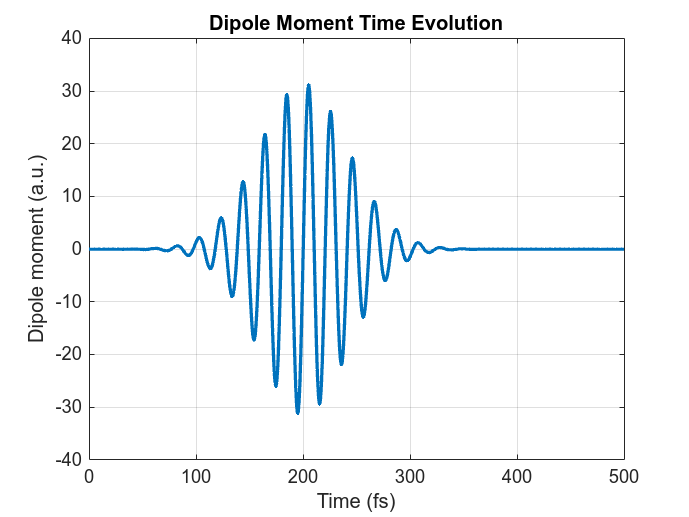



%% ----------------------------------------------------
%  Load dipole evolution data
% -----------------------------------------------------
dip = readmatrix('dipole_time_evolution.txt');
t      = dip(:,1);
d      = dip(:,2);

au_s = 2.41888e-17;
au_fs = au_s * 1e15;

t_fs = t * au_fs;

figure;
plot(t_fs, d, 'LineWidth', 1.8); grid on;
xlabel('Time (fs)');
ylabel('Dipole moment (a.u.)');
title('Dipole Moment Time Evolution');